# Summarize the sex and ages of the SVIP Released data set

BW/RF PoST Team, 2016

## Open up the scitran client

st = scitran('scitran');

## Find the sessions in the SVIP Released project

sessions = st.search('sessions',...
    'project label contains','SVIP Released');
fprintf('Number of sessions:  %d\n',length(sessions))

Number of sessions:  283



%% Get the subject information from those sessions
subjects = stSubjectInfo(sessions);

% Specifically the ages
ages = stSubjectGet(subjects,'age');

% Summarize
fprintf('Total subjects %d  (unknown ages %d)\n',length(subjects),sum(ages==0));

Total subjects 283  (unknown ages 0)


## Plot the age distribution

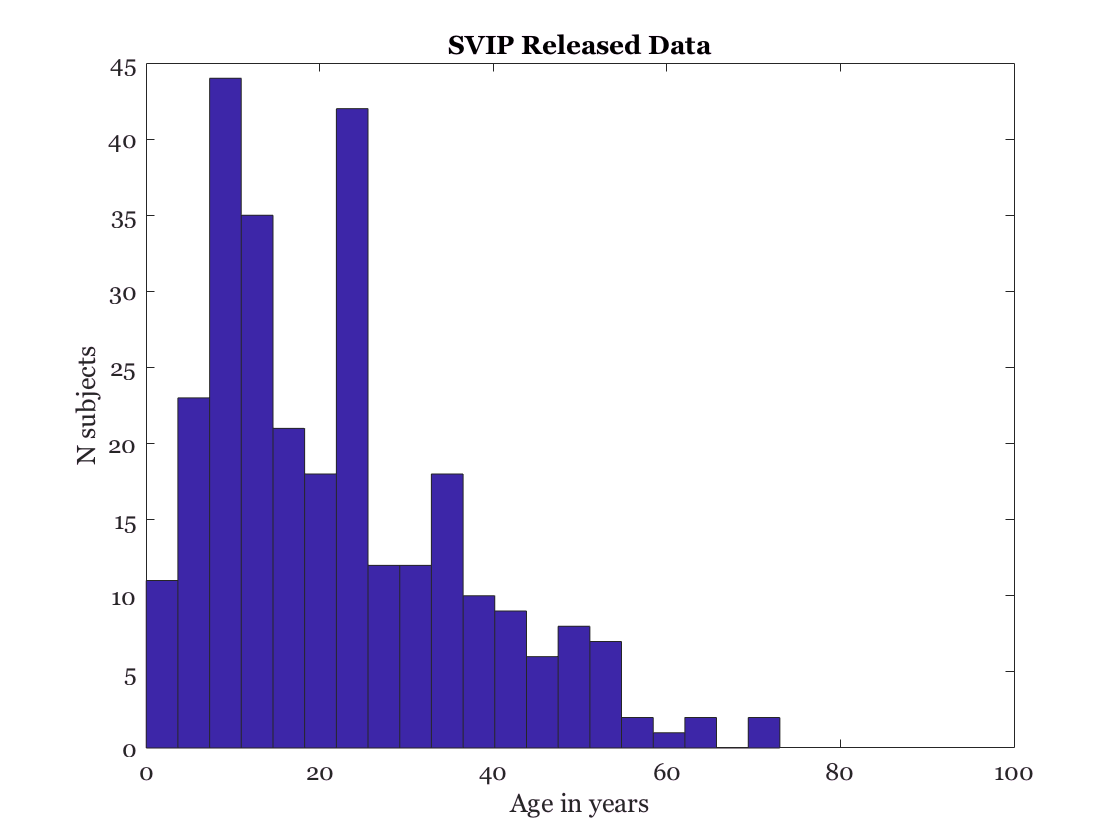

figure;
hist(ages,20); xlabel('Age in years'); ylabel('N subjects');
set(gca,'xlim',[0 100]);
title(sprintf('%s',srch.projects.match.label));

## Sex distribution


sex = stSubjectGet(subjects,'sex');
nMale    = sum(sex=='m');
nFemale  = sum(sex =='f');
nUnknown = sum(sex == 'u');
fprintf('%d Males\n%d Females\n%d Unknown\n',nMale,nFemale,nUnknown);

160 Males
123 Females
0 Unknown
